# Piezoelectric Sensor 

Copyright (C) [2022](#2020) [Bolic](#Miodrag)

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES

## Introduction

This notebook provides introduction to piezoelectric sensors and their models. 

The word piezoelectricity originates from Greek and means electricity due to pressure. The piezoelectric effect is electric charges being generated when mechanical forces are applied to a material. When these piezoelectric materials are used in sensors, they can be used in a vast array of applications.

Piezoelectric transducers are commonly used in a variety or biomedical applications and are parts of pressure transducers, accelerometers, microphones, ultrasound systems and so on. Piezoelectric transducers after applied force induce charge and in this way they represent active transducers. Also, when the electric field is applied, piezoelectric materials can be used as actuators because the generates the strain. 

Sensors typically contain a transduction element and a sensing element. The sensing element will produce a measurable response to the change in physical condition while the transduction element is converting the sensor output into another form. In piezoelectric sensors, the transduction element corresponds to the sensing element and is a material that has piezoelectric properties. Piezoelectric sensors are classified as active sensors since they do not require external power to achieve an electrical output [1].  

Our goals are to: 

- Model a piezoelectric sensor in Simscape 

- Plot step displacemt of the sensor 

- Plot the response of the sensor 

- Compute the sensitivity of the sensor 

## Model of Piezoelectric Sensor  

Piezoelectric sensor can be modeled using the circuit shown below. 

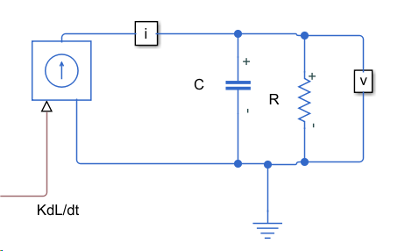

R includes the total leakage resistance of the piezoelectric crystal together with the input impedance of the amplifier. The leakage resistance of the piezoelectric crystal is in the order of GΩ and the input resistance of the connected amplifier is in the order of MΩ. Typical capacitance of the transducer is in the order of 1 nF. In this example, R=10 MΩ and C= 1nF. The i and v are represent ampermeter and voltmeter. 

## Current Source 

The current source that is externally driven was used in the model and created below. 

clear all

Iin(:,1)=0:0.001:0.25; %time
L(1)=0;
L(2)=5e-9;
L(3:120)=1e-8; % displacement
L(121)=5e-9;
L(122:251)=0;
Iin(:,2)=[0 diff(L)];
simOut = sim('Piezoelec1', 'CaptureErrors', 'on');

## Step Displacement and Response 

First, plot for a step displacement of the transducer:

figure
a1=plot(Iin(:,1),L*1e9)

a1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×251 double]
              YData: [1×251 double]
              ZData: [1×0 double]

  Show all properties


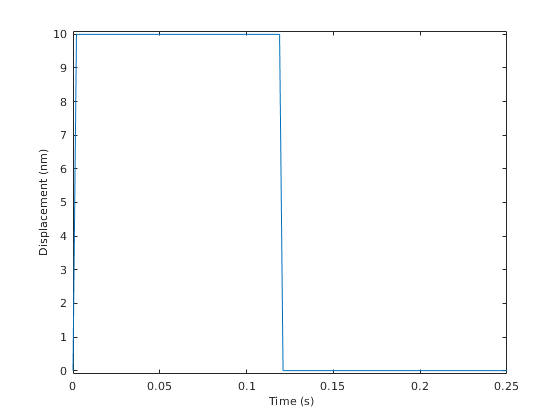

xlabel(' Time (s)', 'FontSize', 10)
ylabel('Displacement (nm)', 'FontSize', 10)
ylim([-.1 10.1])

The time constant of the transducer/amplifier system is 10 ms and the step response drops to zero at about 50 ms as can be seen in the plot above.

Now, plot for the response of the transducer:

figure
a1=plot(simOut.current_out.Time,50*simOut.voltage_out.Data)

a1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×91 double]
              YData: [1×91 double]
              ZData: [1×0 double]

  Show all properties


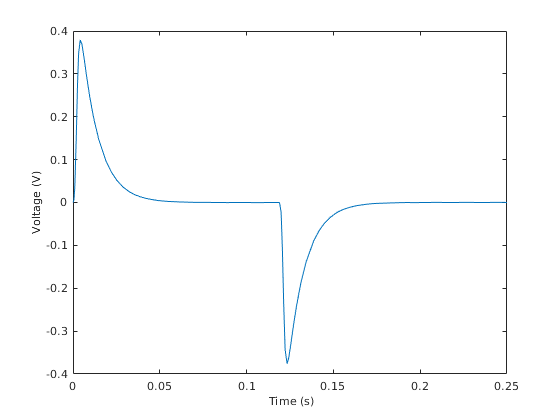

xlabel(' Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)

## References 

[1] A. Arnau, *Piezoelectric transducers and applications*, 2nd ed. New York: Springer, 2010, pp.1-4.

[2] J. G. Webster (Ed.), *Medical Instrumentation: Application and Design*, John Wiley & Sons, 4rd Edition, 2010.